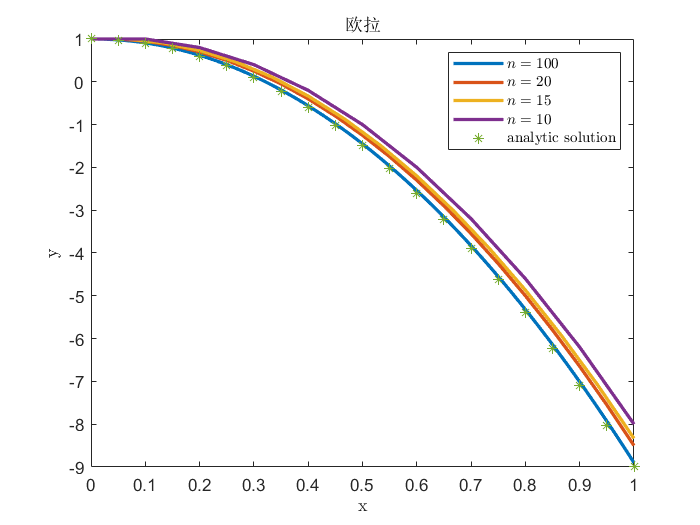

clc,clear,close all
cd C:\Users\sweetie\Desktop\微分方程\code\作图
for n = [100,20,15,10]
    syms x y
    dif_f = @(x,y) -20*x;
    h = 1/n;
    a = 0;
    b = 1;
    y0 = 1;
    x = a:h:b;
    y = euler(dif_f,a,b,h,y0);
    plot(x,y,'LineWidth',2)
    hold on
end

x = 0:0.05:1;
y = -10*x.^2+1;
plot(x,y,'*')
legend({'$n=100$','$n=20$','$n=15$','$n=10$','analytic solution'},"FontName",'Times New Roman','Interpreter',"latex")
xlabel('x','Interpreter',"latex")
ylabel('y','Interpreter',"latex")
str = '欧拉';
title(str)
cd C:\Users\sweetie\Desktop\微分方程\fig
print(str,'-depsc')